# 4. Semesterproject

%Settings
sympref('MatrixWithSquareBrackets',true)

ans = logical
   1


## Declaring variables for the two systems

### Cart

clc; clear;
syms x              % [m]       position 
syms x_dot_c        % [m/s]     velocity
syms x_ddot_c       % [m/s^2]   acceleration
syms T_c            % [N]       tension force
syms F_c            % [N]       external force

m_c = 0.5           % [Kg]      mass of cart

m_c = 0.5000

b_c = 5             % [N/(m/s)] damping coefficient, cart

b_c = 5

g = 9.82            %           gravity coefficient

g = 9.8200

F_gc = m_c*g        %           gravity for cart

F_gc = 4.9100

F_n = F_gc          %           normal force

F_n = 4.9100

F_dc = b_c*x_dot_c

$$F\_dc = 5\,{\dot{x}}_{c}$$

### Pendulum

syms theta             % [rad]     angle of pendulum
syms theta_dot         % [rad/sec] angle velocity
syms theta_ddot        % [rad/sec^2] angle acceleration
syms tau_e             % [Nm]      external torque
syms t_p               %           tension of pendulum
syms F_dist            % [N]       disturbance force
syms F_gp              % [N]       gravity of pendulum


m_p = 0.084            % [Kg]      mass of the pendulum

m_p = 0.0840

m_rod = 0.082          % [Kg]      mass of the rod

m_rod = 0.0820

m_wa = 0.002           % [Kg]      mass of the weight attached

m_wa = 0.0020

l_rod = 0.35           % [m]       length of rod

l_rod = 0.3500

l_p = (m_rod*(l_rod/2)+m_wa*l_rod)/(m_rod+m_wa)         % [m] length to center of mass

l_p = 0.1792

b_p = 0.0012                                            % [N/(m/s)] damping coefficient, pendulum

b_p = 0.0012

F_dp = b_p*theta_dot                                    % [N] damping force of pendulum

$$F\_dp = \frac{3\,\dot{\theta }}{2500}$$

h = l_p*cos(theta)                                      % [m] height of pendulum/ y component

$$h = \frac{43\,\cos\left(\theta \right)}{240}$$

## Linearized Differential equations, for $\ddot{x_c } \;,\ddot{\theta}$


$$\ddot{x_c } =\frac{F_c }{m_c }-\frac{b_c }{m_c }\cdot \dot{x_c } -\frac{b_p }{m_c \cdot l_p }\cdot \dot{\theta} +\frac{m_p \cdot g}{m_c }\cdot \theta$$


x_ddot_c = (F_c/m_c)-(b_c/m_c)*x_dot_c-(b_p/(m_c*l_p))*theta_dot+((m_p*g)/(m_c))*theta

$$x\_ddot\_c = 2\,F_{c}+\frac{10311\,\theta }{6250}-\frac{72\,\dot{\theta }}{5375}-10\,{\dot{x}}_{c}$$


$$\ddot{\theta} =-\frac{b_p }{m_p \cdot l_p^2 }\cdot \frac{m_c +m_p }{m_c }\cdot \dot{\theta} +\frac{F_c }{m_c \cdot l_p }-\frac{b_c }{m_c \cdot l_p }\cdot \dot{x_c } +\frac{g}{l_p }\cdot \frac{m_c +m_p }{m_c }\cdot \theta$$


theta_ddot = -(b_p/(m_p*l_p^2))*((m_c+m_p)/m_c)*theta_dot+(F_c/(m_c*l_p))-(b_c/m_c*l_p)*x_dot_c+(g/l_p)*((m_c+m_p)/m_c)*theta

$$theta\_ddot = \frac{480\,F_{c}}{43}+\frac{281550909495071\,\theta }{4398046511104}-\frac{2340939283092633\,\dot{\theta }}{4503599627370496}-\frac{43\,{\dot{x}}_{c}}{24}$$

## State space model


$$\dot{x_{\textrm{state}} } =\frac{d}{\textrm{dt}}\left\lbrack x_{\textrm{state}} \right\rbrack =\left\lbrack \begin{array}{c}
\dot{x_c } \\
\ddot{x_c } \\
\dot{\theta} \\
\ddot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & -\frac{b_c }{m_c } & \frac{m_p \cdot g}{m_c } & -\frac{b_p }{m_c \cdot l_p }\\
0 & 0 & 0 & 1\\
0 & -\frac{b_c }{m_c \cdot l_p } & \frac{g}{l_p }\cdot \frac{m_c +m_p }{m_c } & -\frac{b_p }{m_p \cdot l_p^2 }\cdot \frac{m_c +m_p }{m_c }
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x_c \\
\dot{x_c } \\
\theta \;\\
\dot{\theta \;} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m_c }\\
0\\
\frac{1}{m_c \cdot l_P }
\end{array}\right\rbrack \cdot F_c$$


A = [0 1 0 0; 0 -(b_c/m_c) (m_p*g)/m_c -(b_p/(m_c*l_p)); 0 0 0 1; 0 -(b_c/(m_c*l_p)) (g/l_p)*((m_c+m_p)/m_c) -(b_p/(m_p*l_p^2))*((m_c+m_p)/m_c)]

A =          0    1.0000         0         0
         0  -10.0000    1.6498   -0.0134
         0         0         0    1.0000
         0  -55.8140   64.0173   -0.5198


B = [0; 1/m_c; 0; 1/(m_c*l_p)]

B =          0
    2.0000
         0
   11.1628


C = [1 0 0 0; 0 0 1 0] % cart position, pendul angle

C =      1     0     0     0
     0     0     1     0


D=0;

states = {'x','x_dot_c','theta','theta_dot'};
inputs = {'u'};
outputs = {'x_c';'theta'};

% Statespace object
sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

sys_ss =
 
  A = 
                      x    x_dot_c      theta  theta_dot
   x                  0          1          0          0
   x_dot_c            0        -10       1.65    -0.0134
   theta              0          0          0          1
   theta_dot          0     -55.81      64.02    -0.5198
 
  B = 
                  u
   x              0
   x_dot_c        2
   theta          0
   theta_dot  11.16
 
  C = 
                  x    x_dot_c      theta  theta_dot
   x_c            1          0          0          0
   theta          0          0          1          0
 
  D = 
          u
   x_c    0
   theta  0
 
Continuous-time state-space model.




% Transferfunction from statespace
sys_tf = tf(sys_ss)

sys_tf =
 
  From input "u" to output...
               2 s^2 + 0.8901 s - 109.6
   x_c:  -------------------------------------
         s^4 + 10.52 s^3 - 59.57 s^2 - 548.1 s
 
                  11.16 s - 6.572e-16
   theta:  ---------------------------------
           s^3 + 10.52 s^2 - 59.57 s - 548.1
 
Continuous-time transfer function.




% individual transfer functions
[num,denum] = tfdata(sys_tf)

num = 2×1 cell array
    {[0 0 2.0000 0.8901 -109.6186]}
    {[    0 0 11.1628 -6.5725e-16]}


denum = 2×1 cell array
    {[1 10.5198 -59.5670 -548.0930 0]}
    {[  1 10.5198 -59.5670 -548.0930]}


sys_tf_cartPos = tf(num(1),denum(1))

sys_tf_cartPos =
 
        2 s^2 + 0.8901 s - 109.6
  -------------------------------------
  s^4 + 10.52 s^3 - 59.57 s^2 - 548.1 s
 
Continuous-time transfer function.



sys_tf_pendAng = tf(num(2),denum(2))

sys_tf_pendAng =
 
         11.16 s - 6.572e-16
  ---------------------------------
  s^3 + 10.52 s^2 - 59.57 s - 548.1
 
Continuous-time transfer function.



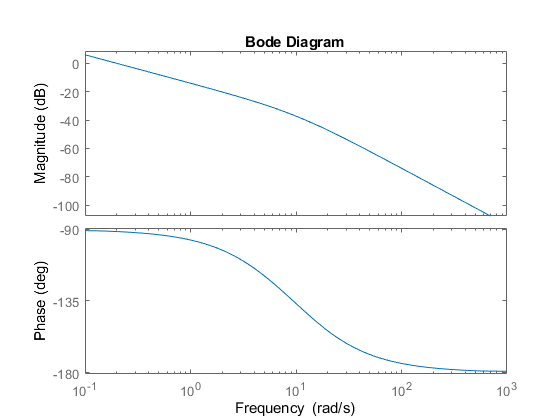


bode(sys_tf_cartPos)

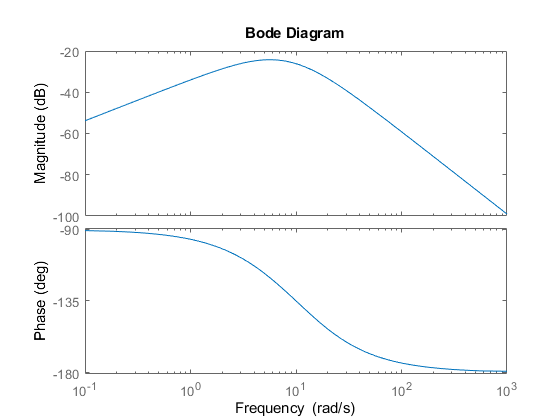

bode(sys_tf_pendAng)

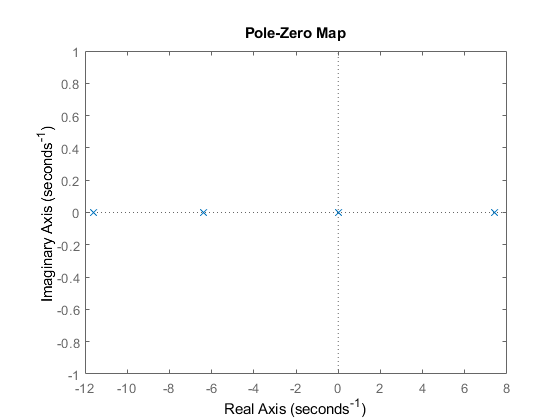


pzmap(sys_tf)

eigenval = eig(A) % have a eigenval at 7.49 -> unstable.

eigenval =          0
  -11.5752
   -6.3737
    7.4291


From the eigenvalues we can determind, that the system is unstable. We wish to have the eigenvalues in the left side -> to stabilize the system. This can be done by designing a Controller. 

Little function to test with other C-matrixes

% prompt = (['What output do you want?: ' newline...
%     '1 = cart position: ' newline...
%     '2 = cart velocity: ' newline...
%     '3 = pendulum angle: ' newline...
%     '4 = pendulum angle velocity: ' newline...
%     '5 = show all: ' newline...
%     'else a default C is defined, cart position and pendulum angle' newline]) 
% input = input(prompt)
% switch(input)
%     case 1
%         fprintf('cart position')
%         C =[1 0 0 0]
%     case 2
%         fbprintf('cart velocity')
%         C = [0 1 0 0]
%     case 3
%         fprintf('pendulum angle')
%         C = [0 0 1 0]
%     case 4
%         fprintf('pendulum angle velocity')
%     case 5 
%         fprintf('show All, C_general')
%         C = eye(4)   % Shows all pos, and velocities, just for test. 
%     otherwise
%         fprintf('Cart pos, pendulum angle')
%         C = [1 0 0 0; 0 0 0 0; 0 0 1 0; 0 0 0 0]    % C for cart pos, and pendulum angle
% end
% sys_ss = ss(A,B,C,D)
% step(sys)

## Classic Control System Design - Analyse

Noter: System er ustabilt

Udkast til nogle krav:

- Settelingtime : less than 3 sec

- $\alpha %$: Pendulun should not move more than 5 degrees $\approx 0\ldotp 087\;\textrm{radians}$ from vertical position

- Max overshoot, $r_p$ på 45 grader $\approx 0\ldotp 7854\;\textrm{radians}$. (Could be difficult to "save", if higher) 

- rise time 1 sec

### Udregning af specifikationer

hint: lektion 5, slide 13 og 18

% Specs for pendulum
T = 1/100       % [seconds] Sample tim for discrete 

T = 0.0100

t_r = 1         % [Seconds] Rise time

t_r = 1

t_s = 3         % [Seconds] 

t_s = 3

M_p = pi/4      % [Radians] Overshoot, i ikke procent

M_p = 0.7854

alpha = 0.08    % Alpha værdi, have divide with 100

alpha = 0.0800


% Beregner
w_n = 1.8/t_r                                           % [Hz] udæmpet naturlige frekvens

w_n = 1.8000

zeta = sqrt(((log(M_p)/-pi)^2)/(1+((log(M_p))/-pi)^2))  % [Radians] overshoot smaller than M_p

zeta = 0.0767

sigma = (-log(alpha/100))/t_s                           % Unitless

sigma = 2.3770

%NOTER%

Har nu en ide om hvor polerne skal være indenform, for at få et system som lever op til de satte specifikationer.

### Root Locus

Root locus methos gives the oppiturnity to predict how the poles of a system will change depending on the controller gain. We have instered the performace specifications, in megneta. For the system to up-hold the performance, its desiable that the poles are to the left of the lines.

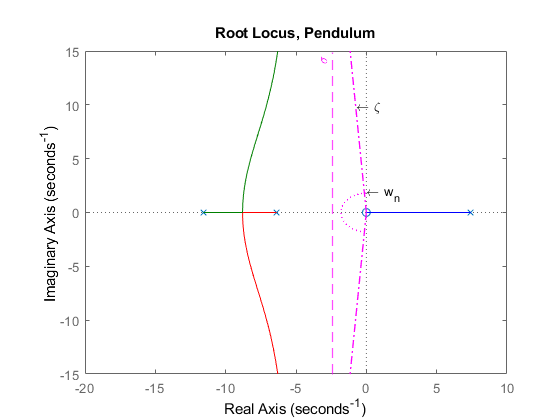

% Root Locus; Pendulum
figure('name', "Root Locus, Pendulum, Plant")
hold on
rlocus(sys_tf_pendAng)
title('Root Locus, Pendulum')
theta = linspace(-pi/2, pi, 100) + linspace(pi, pi/2, 100); % Make half a circle
x = w_n*cos(theta);
y = w_n*sin(theta);
plot(x,y,'LineStyle',":",'Color','magenta', 'LineWidth',1); % w_n
text(w_n*cos(pi/2),w_n*sin(pi/2),'\leftarrow w_n');
xlim([-20, 10]);
ylim([-15, 15]);

l=20;
x2 = 0+(l*cos(asin(zeta)+pi/2));
y2 = 0+(l*sin(asin(zeta)+pi/2));

x3 = 0+(l*cos((3*pi)/2 - asin(zeta)));
y3 = 0+(l*sin((3*pi)/2 - asin(zeta)));

plot([0 x2],[0 y2],[0 x3],[0 y3],'LineStyle',"-.",'Color','magenta', 'LineWidth',1)
text(-0.75,10,'\leftarrow \zeta')
xline(-sigma,'--','\sigma','LabelHorizontalAlignment', 'left','Color', 'magenta', 'LineWidth',1) % sigma
hold off

Pole and zero (remember, Rlocus plots the cl, but the poles and zeros are ol. ) is in the right-halfplane -> unstable system. No matter the gain, it will not stabilize that. -> Need to cancel out. 

%Noter%

vil have min loki (linjer) indenfor specs. 

openloop -> plant*controller

- En hel gren i højre-halv plan -> cancel out, ved at tilføje en pol i origo (Integrator, K_i)

Root locus hjælp til gain værdier -> PID, lead lag compensator -> placer poler og nulpkt -> loki linjer -> finde gain, close loop gain -> sker ved (lyserøde firkanter -> gain -> flytter sig)

## PID - Controller

% PID Controller controlSystemDesigner(sys_tf_pendAng,K)
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



Kp = 1;
Ki = 1;
Kd = 1;
n = 10; %  filter coefficient lek 4 slide 19
P = Kp;
I = Ki*(1/s);
D = Kd * (n/(1+n*(1/s)))

D =
 
   10 s
  ------
  s + 10
 
Continuous-time transfer function.



K = P+I+D % Controller, PID

K =
 
  11 s^2 + 11 s + 10
  ------------------
      s^2 + 10 s
 
Continuous-time transfer function.



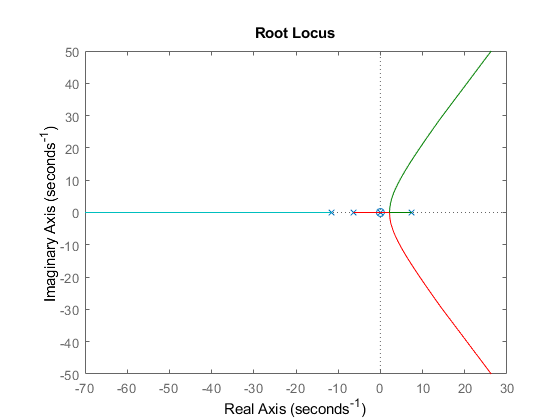

rlocus(sys_tf_pendAng*I)

### % Noter % Forklare det

- Bruge PID til at stabilisere -> vigtere end hvordan vi har fået det. 

- Kan bruge controlSystemDesigner

- Fremgangsmetode:

- Root Locus (samme samme Kp = 1 og Ki=0 ect. ) -> PID controller / Controller (znm) -> Overholder det performance/step response. -> Zeigler Nioco til at skabe udgang -> Eksperimentiel tilgang

% % Test PID
% Kp = 100;
% Ki = 1;
% Kd = 20;
% C = pid(Kp,Ki,Kd);
% T = feedback(sys_tf_pendAng,C);
% t = 0:0.1:10
% impulse(T,t)
% axis([0, 2.5, -0.2, 0.2]);
% title({'Response of Pendulum Position to an Impulse Disturbance';'under PID Control: Kp = 1, Ki = 1, Kd = 1'});

% l_t = 1.78
% C_angle = [0 0 1 0]
% sys_pendulum = ss(A,B,C_angle,D)
% PendController = pidtune(sys_pendulum,'PIDF')



% Root Locus; Cart
% figure('name',"Root Locus, Cart")
% hold on
% rlocus(sys_tf_cartPos)
% title('Root Locus, Cart')
% theta = linspace(-pi/2, pi, 100) + linspace(pi, pi/2, 100); % Make half a circle
% x = w_n*cos(theta);
% y = w_n*sin(theta);
% plot(x,y,'LineStyle',":",'Color','magenta', 'LineWidth',1); % w_n
% text(w_n*cos(pi/2),w_n*sin(pi/2),'\leftarrow w_n');
% xlim([-20, 10]);
% ylim([-15, 15]);
% 
% l=20;
% x2 = 0+(l*cos(asin(zeta)+pi/2));
% y2 = 0+(l*sin(asin(zeta)+pi/2));
% 
% x3 = 0+(l*cos((3*pi)/2 - asin(zeta)));
% y3 = 0+(l*sin((3*pi)/2 - asin(zeta)));
% 
% plot([0 x2],[0 y2],[0 x3],[0 y3],'LineStyle',"-.",'Color','magenta', 'LineWidth',1)
% text(-0.75,10,'\leftarrow \zeta')
% xline(-sigma,'--','\sigma','LabelHorizontalAlignment', 'left','Color', 'magenta', 'LineWidth',1) % sigma
% hold off

% Export figure
% exportgraphics(gcf,'./figures/rootLocus_cart.eps','ContentType','vector');

## SAVE IMPORTANT VARIABLES

save('params','-append','sys_ss', 'sigma', 'states', 'inputs', 'outputs', 'm_c')